# MAE - 5780 Mid Term Project, Pinhole camera

## Saksham Kaushik (sk2482)

### Defining Discrete time state space model

clear
dt = 0.01;
t = 0:dt:10;
nt = length(t);
b1 = 100;
b2 = 100;

A = [1,0,dt,0;0,1,0,dt;0,0,1,0;0,0,0,1];
B = [0,0; 0,0; b1,0;0,b2];
C = [1,0,0,0;0,1,0,0];
D = [0,0;0,0];

sys_cam = ss(A,B,C,D,dt);

%generating open loop control input
% u = zeros(2,nt);
u1 = [zeros(2,250),[0,0.065*pi/50]',zeros(2,49),[0,-0.065*pi/50]'];
u2 = [zeros(2,200),[0,0.09*pi/50]',zeros(2,49),[0,-0.09*pi/50]'];
u3 = [zeros(2,200),[0,0.08*pi/50]',zeros(2,49),[0,-0.08*pi/50]'];
u = [u1,u2,u3,zeros(2,198)];

%camera position and parameters
xc = [5,5,5];

a = 36/1000; %36mm
b = 27/1000; %27mm
lmbda = 100/1000; %50mm

%initial state
x0 = [0,0.74*pi,0.8*pi,0];
%Simulating camera state
[y,t,x] = lsim(sys_cam,u,t,x0);

%Initial FOV
figure(1)
clf
F = find_fov(x0(1:2),xc,a,b,lmbda);
% plot_FOV(F,0,0)

## Plotting Pan and Tilt response

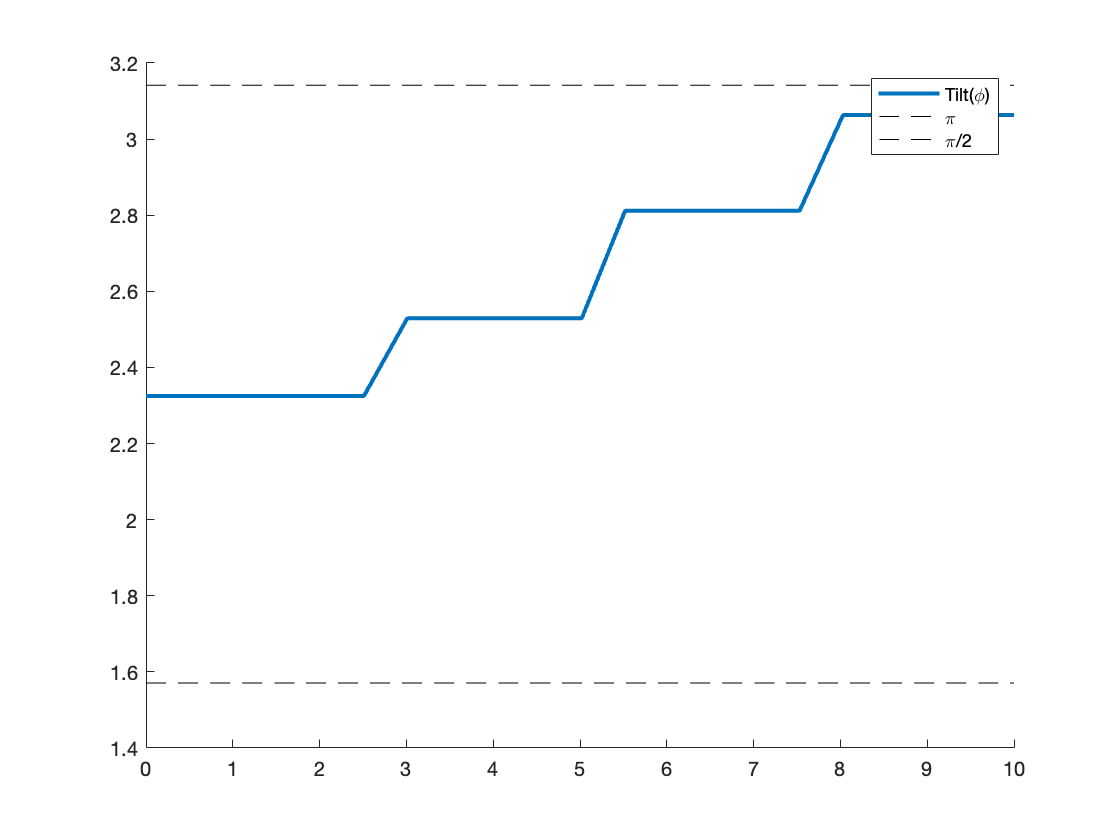

figure(3)
clf
hold on
plot(t,x(:,2),'LineWidth',2)
plot(t,ones(1,nt)*pi,'--k',t,ones(1,nt)*pi/2,'--k')
legend('Tilt(\phi)','\pi','\pi/2')
hold off

## Plotting FOV motion

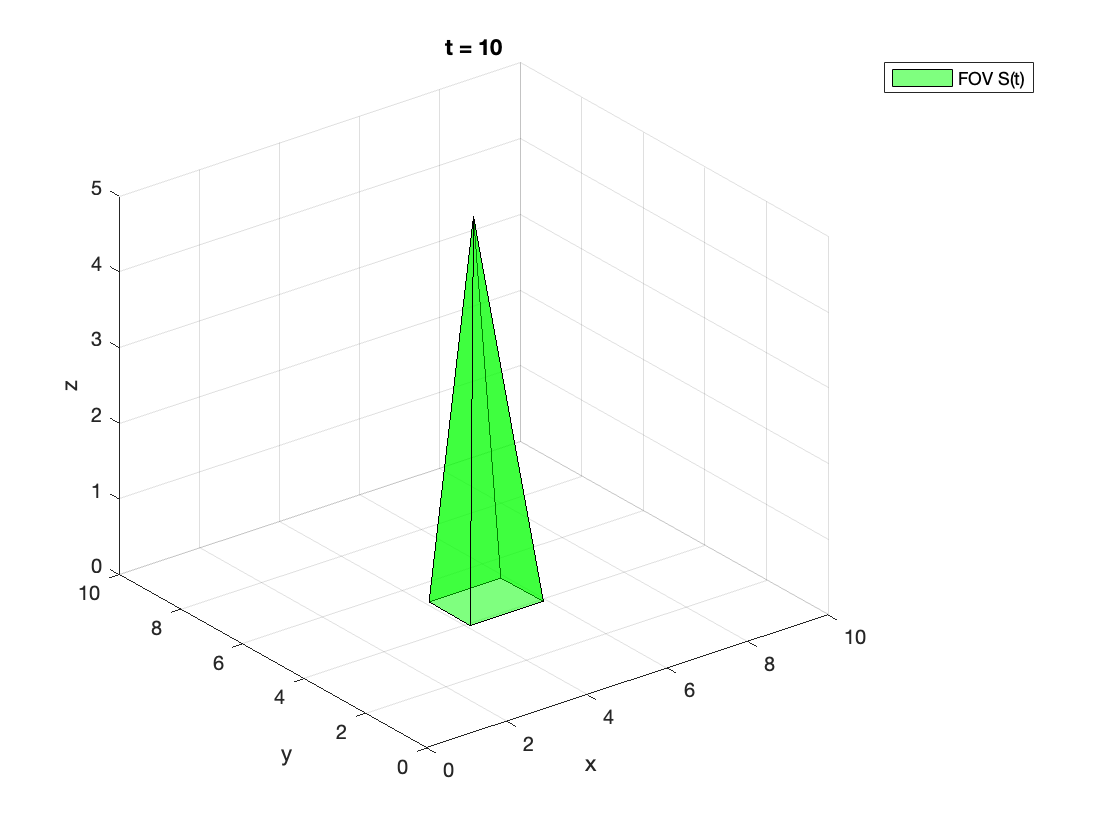

v = VideoWriter('FOV','MPEG-4');
v.Quality = 100;
v.FrameRate = 80;
open(v);
figure(2)
for i = 1:nt
    clf
    F = find_fov(x(i,1:2),xc,a,b,lmbda);
    plot_FOV(F,0,t(i));
    frame = getframe(gcf);
    writeVideo(v,frame);
end

close(v)

## Simulation:

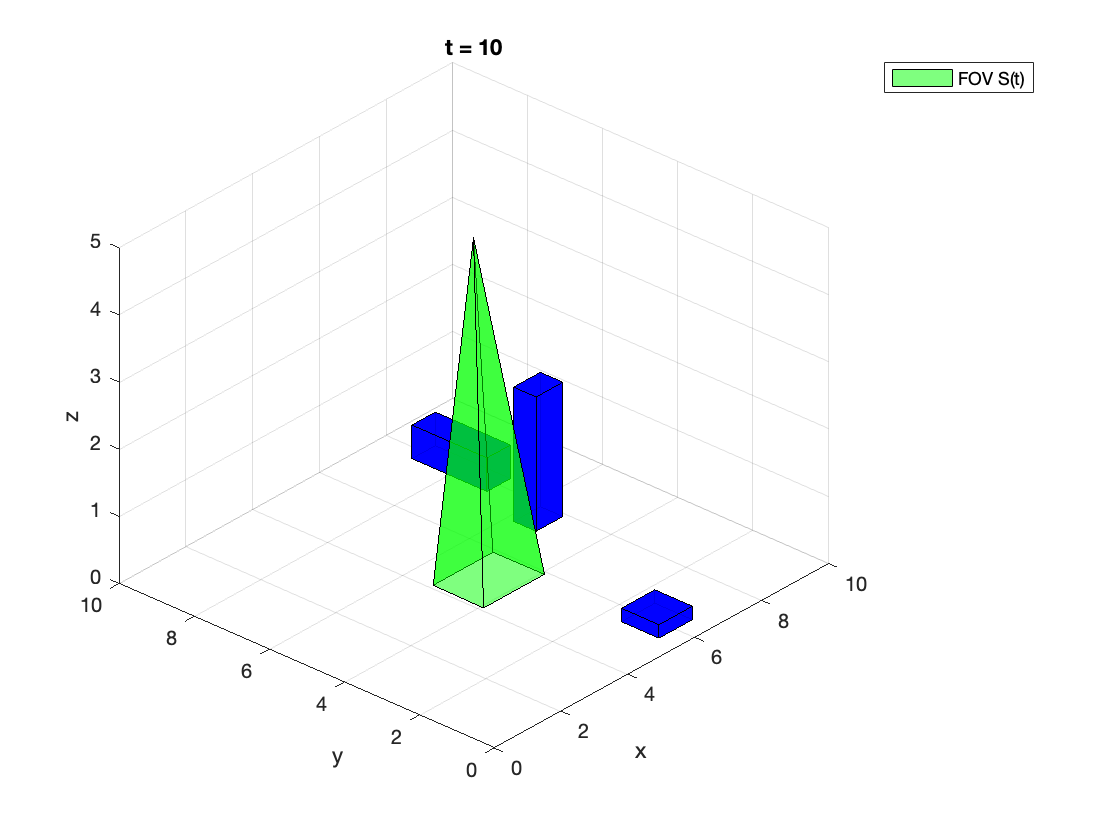

%Defining targets and their trajectories%%%%%%%%%%%%%%%%%%%%%%%%%%
x0 = [2.5,2.5,0.5,0.3;2,8,0.6,0;8,4,-0.2,-0.3];
u_target = zeros(2,nt);
moving_target(1) = define_moving_target(x0(1,:),u_target,0.8,0.6,2,dt,t);
moving_target(2) = define_moving_target(x0(2,:),u_target,0.7,2,0.5,dt,t);
moving_target(3) = define_moving_target(x0(3,:),u_target,1,1,0.2,dt,t);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure(7)
clf
% plot_moving_cube(moving_target,1,0)
v = VideoWriter('moving_targets','MPEG-4');
v.Quality = 100;
v.FrameRate = 80;
open(v);
for i = 1:nt
    clf
    F = find_fov(x(i,1:2),xc,a,b,lmbda);
    detection = check_intersection_t(F,moving_target,i,t(i));
    hold on
    plot_FOV(F,detection,t(i));
    plot_moving_cube(moving_target,i,t(i))
    legend('FOV S(t)');
    hold off
    frame = getframe(gcf);
    writeVideo(v,frame);
end

close(v)

## Simulation Functions

function F = find_fov(x,xc,a,b,lmbda)
%Returns 4 vertices of the FOV on ground plane and the camera position as a
% 3x5 matrix

% INPUTS: x = state vector
%         xc = camera position
%         a,b = size of image sensor (in meters)
%         lmbda = focal length of camera

% OUTPUTS: F = 3x5 matrix of vertices forming camera FOV in 3D

    %FOV vertices in camera frame
    q1 = [a/2 b/2 lmbda];
    q2 = [a/2 -b/2 lmbda];
    q3 = [-a/2 b/2 lmbda];
    q4 = [-a/2 -b/2 lmbda];

    Q = [q1' q2' q3' q4'];

    psi = x(1);
    phi = x(2);

    %Rotation matrices
    H_psi = [cos(psi),-sin(psi),0;
    sin(psi),cos(psi),0;
    0, 0, 1];
    
    H_phi = [1, 0, 0;
    0, cos(phi), -sin(phi);
    0, sin(phi), cos(phi)];

    r1 = -xc(3)/(0.5*b*sin(phi) + lmbda*cos(phi));
    r2 = -xc(3)/(-0.5*b*sin(phi) + lmbda*cos(phi));
    r3 = r1;
    r4 = r2;
    
    Q_I_temp = H_psi*H_phi*Q;
    
    Q_I = [r1*Q_I_temp(:,1),r2*Q_I_temp(:,2),r3*Q_I_temp(:,3),r4*Q_I_temp(:,4)];
    
    X_L = repmat(xc,4,1)' + Q_I;
   
    F = [xc', X_L];

end


function target = define_moving_target(x0,u,l,b,h,dt,t)
%defines struct target containing 2D array of all its locations through
%time and the targets size(l,b,h)

% INPUTS: x0 = target initial position
%         u: target control input
%         l: length of target
%         b:breadth of target
%         h: height of target
%         dt: time step size
%         t: time array

% OUTPUTS: target struct

    A = [1,0,dt,0;0,1,0,dt;0,0,1,0;0,0,0,1];
    B = [0,0; 0,0; 0.1,0;0,0.1];
    C = [1,0,0,0;0,1,0,0];
    D = [0,0;0,0];
    
    sys_target = ss(A,B,C,D,dt);
    y = lsim(sys_target,u,t,x0);
    
    target.location = y;
    target.length = l;
    target.breadth = b;
    target.height = h;
   
end

function result = check_intersection_t(F,targets,t_index,t)
%checks if any of the targets are intersecting with the FOV

% INPUTS: F: vertices of FOV
%         targets: array of target structs to be checked
%         t_index: index of the current time-step
%         t: time array

% OUTPUTS: logical value 0 or 1 for no detection and detection respectively
    
    N = length(targets);
    result = 0;
    for i = 1:N
        target = targets(i);
        xt = target.location(t_index,1);
%         xt = 4 + 2*cos(5/2/pi*t);
        yt = target.location(t_index,2);
%         yt = 4 + 2*sin(5/2/pi*t);
        l = target.length;
        b = target.breadth;
        h = target.height;

        shp = alphaShape(F');

        x_range = linspace((xt-l/2),(xt+l/2),5);
        y_range = linspace((yt-b/2),(yt+b/2),5);
        z_range = linspace(0,h,5);
        [X,Y,Z] = meshgrid(x_range,y_range,z_range);

        result = result + sum(inShape(shp,X,Y,Z),'all');
    end

end

## Plotting Functions


function plot_FOV(F,detection,t)
%Plots FOV of camera at given time

% INPUTS: F = vertices of FOV
%         detection: 1 or 0, corresponding to whether there is a detection
%         or not
%         t = time

% OUTPUTS: plot

    if(detection)
        clr = 'red';
    else
        clr = 'green';
    end

    FV.Vertices = F';
    FV.Faces = [1 2 3; 1 2 4; 1 3 5; 1 5 4];
    FV.FaceColor = clr;
    patch(FV,'FaceAlpha',0.5)
    view (3)
    xlim([0 10]);
    ylim([0 10]);
    zlim([0 5]);
    xlabel('x');
    ylabel('y');
    zlabel('z');
    legend('FOV S(t)');
    grid on;  
    title(append('t = ',num2str(t)));
    
end

function plot_moving_cube(targets,t_index,t)

    N = length(targets);
    hold on
    for i = 1:N
        target = targets(i);
        xt = target.location(t_index,:);
        l = target.length;
        b = target.breadth;
        h = target.height;

        x = xt(1);
%         x = 4 + 2*cos(5/2/pi*t);
        y = xt(2);
%         y = 4 + 2*sin(5/2/pi*t);

        V = [x-l/2, y+b/2, h;x+l/2, y+b/2, h;x+l/2, y+b/2, 0;x-l/2, y+b/2, 0;
            x-l/2, y-b/2, 0;x-l/2, y-b/2, h;x+l/2, y-b/2, h;x+l/2, y-b/2, 0];
        FV.Vertices = V;
        FV.Faces = [1 2 3 4;5 6 7 8;1 4 5 6;2 3 8 7; 3 4 5 8; 1 2 7 6];
        FV.FaceColor = 'blue';
        patch(FV,'FaceAlpha', 0.9);
        view(3)
    end
    hold off
    xlim([0 10]);
    ylim([0 10]);
    zlim([0 5]);
    xlabel('x');
    ylabel('y');
    zlabel('z');
    grid on;  
end
